# MASS SPRING

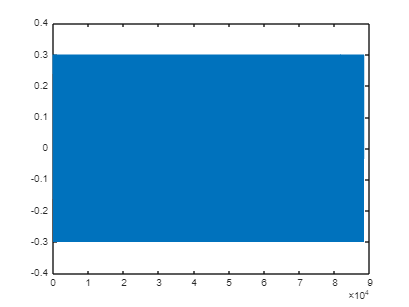

% overall variables
fs = 44100;
k = 1/fs;
time = 2*fs;

% spring
fSpring = 200; % frequency of the spring

% coefficients
cSpring = 2-k^2*(2*pi*fSpring)^2; % scheme coefficients considering given frequency

% set inital placement
uSpring0 = 0.3;
springV = 0;

%  intialize scheme state
uSpring1 = uSpring0 + k*springV;
uSpring2 = uSpring0;

outSpring = zeros(time,1); 

% loop
for n = 1:time
    uSpring = cSpring*uSpring1-uSpring2;
    outSpring(n) = uSpring;
    uSpring2 = uSpring1; uSpring1 = uSpring;
end 

plot(outSpring);

# SIMPLE DAMPED STIFF STRING

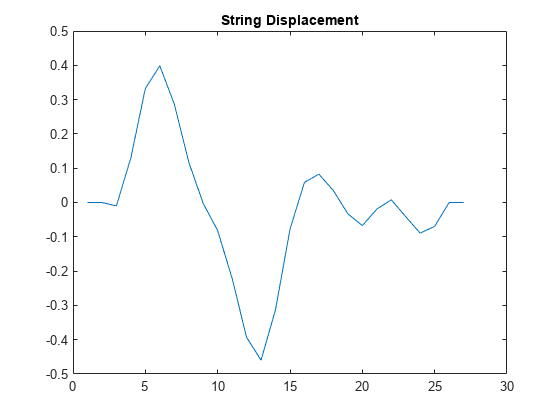


% string
L = 1;  % Length of the string
sigma0 = 1;
sigma1 = 0.005;
f = 200; % frequency of the string
kappa = 30;

c = 200; % wave speed 
h = sqrt(c^2 * k^2 + 4 * sigma1 * k + sqrt((c^2 * k^2 + 4 * sigma1 * k)^2 + 16 * kappa^2 * k^2)/2); % stability condition
N = floor(L / h);
h = L / N;


uNext = zeros (N+1, 1);
u = zeros(N+1, 1);
u(3:9) = hann(7);
uPrev = u;
time =  2*fs;
kappa = 30;
lambda = (c*k/h);



for n = 1:time
    
    uSpring = cSpring*uSpring1-uSpring2;
    outSpring(n) = uSpring;
    uSpring2 = uSpring1; uSpring1 = uSpring;
    
    for l = 3:N-1
       uNext(l) = (2*u(l) - uPrev(l) + ...
           lambda^2 * (u(l+1) - 2 * u(l) + u(l-1)) - (kappa^2 * k^2 / h^4 * (u(l+2) - 4 * u(l+1) + 6 * u(l) - 4 * u(l-1) + u(l-2))) + ...
           sigma0 * k *uPrev(l-1) + ...
           2 * sigma1 * k / h^2 * (u(l+1) - 2 * u(l) + u(l-1) - uPrev(l+1) + 2 * uPrev(l) - uPrev(l-1)))...
           /(1 + sigma0 * k);
    end
    out(n) = u(7);
    
    uPrev = u;
    u = uNext;
    
    plot(uNext);
    drawnow;
end

# CONNECTED SPRING WITH STRING

% overall variables
fs = 44100;
k = 1/fs;
time = 2*fs;


%  spring0  
fSpringlist = 200:1:3500;
samples_Spring = 1; %steps


uSpring0 = 0.05;% set inital placement
springV = 0;
uSpring1 = uSpring0 + k*springV;
uSpring2 = uSpring0;

%  spring1
fSpringlist_1 = 200:1:3500;
samples_Spring_1 = 1; %steps

uSpring0_1 = 0.05;% set inital placement
springV_1 = 0;
uSpring1_1 = uSpring0_1 + k*springV_1;
uSpring2_1 = uSpring0_1;

%  spring2
fSpringlist_2 = 200:1:3500;
samples_Spring_2 = 1; %steps

uSpring0_2 = 0.05;% set inital placement
springV_2 = 0;
uSpring1_2 = uSpring0_2 + k*springV_2;
uSpring2_2 = uSpring0_2;

%  spring3
fSpringlist_3 = 200:1:3500;
samples_Spring_3 = 1; %steps

uSpring0_3 = 0.05;% set inital placement
springV_3 = 0;
uSpring1_3 = uSpring0_3 + k*springV_3;
uSpring2_3 = uSpring0_3;


%% string %%
L = 1;  % Length of the string
sigma0 = 0.1;
sigma1 = 0.00001;

kappa = 0.0006;
c = 0; % wave speed 

%stability
h = sqrt(c^2 * k^2 + 4 * sigma1 * k + sqrt((c^2 * k^2 + 4 * sigma1 * k)^2 + 16 * kappa^2 * k^2)/2); % stability condition
N = floor(L / h);
h = L / N;

uNext = zeros (N+1, 1);
u = zeros(N+1, 1);
u(3:9) = hann(7);
uPrev = u;
lambda = (c*k/h);

out = zeros(1, time);
outSpring =  zeros(1,time);
finalout = zeros(1,time);

triggered = [false, false, false, false];
triggerSample = zeros(1, 4);



for n = 1:time
    
    if n == 1
        uSpring1 = 0.05;  % Re-initialize motion
        uSpring2 = 0;
        triggered(1) = true;
        triggerSample(1) = n;
    end
    if n == fs/2
        uSpring1_1 = 0.05;  % Re-initialize motion
        uSpring2_1 = 0;
        triggered(2) = true;
        triggerSample(2) = n;
    end
    if n == fs
        uSpring1_2 = 0.05;  % Re-initialize motion
        uSpring2_2 = 0;
        triggered(3) = true;
        triggerSample(3) = n;
    end
    if n == fs*1.5
        uSpring1_3 = 0.05;  % Re-initialize motion
        uSpring2_3 = 0;
        triggered(4) = true;
        triggerSample(4) = n;
    end

    sweepIndex = @(tSample) min(floor((n - tSample) / samples_Spring) + 1, length(fSpringlist));
    sweepIndex_1 = @(tSample_1) min(floor((n - tSample_1) / samples_Spring_1) + 1, length(fSpringlist_1));
    sweepIndex_2 = @(tSample_2) min(floor((n - tSample_2) / samples_Spring_2) + 1, length(fSpringlist_2));
    sweepIndex_3 = @(tSample_3) min(floor((n - tSample_3) / samples_Spring_3) + 1, length(fSpringlist_3));

    if triggered(1)
        fSpring = fSpringlist(sweepIndex(triggerSample(1)));
    end
    if triggered(2)
        fSpring_1 = fSpringlist_1(sweepIndex_1(triggerSample(2)));
    end
    if triggered(3)
        fSpring_2 = fSpringlist_2(sweepIndex_2(triggerSample(3)));
    end
    if triggered(4)
        fSpring_3 = fSpringlist_3(sweepIndex_3(triggerSample(4)));
    end

    if n < 1500
    cSpring = 2 - k^2 * (2 * pi * fSpring)^2;
    uSpring = cSpring * uSpring1 - uSpring2;
    uSpring2 = uSpring1;
    uSpring1 = uSpring;
    end
    if n >= fs/2 && n < fs/2+1500
    cSpring_1 = 2 - k^2 * (2 * pi * fSpring_1)^2;
    uSpring_1 = cSpring_1 * uSpring1_1 - uSpring2_1;
    uSpring2_1 = uSpring1_1;
    uSpring1_1 = uSpring_1;
    end
    if n >= fs && n < fs+1500
    cSpring_2 = 2 - k^2 * (2 * pi * fSpring_2)^2;
    uSpring_2 = cSpring_2 * uSpring1_2 - uSpring2_2;
    uSpring2_2 = uSpring1_2;
    uSpring1_2 = uSpring_2;
    end
    if n >= fs*1.5 && n < fs*1.5+1500
    cSpring_3 = 2 - k^2 * (2 * pi * fSpring_3)^2;
    uSpring_3 = cSpring_3 * uSpring1_3 - uSpring2_3;
    uSpring2_3 = uSpring1_3;
    uSpring1_3 = uSpring_3;
    end

   
    for l = 3:N-2
        uNext(l) = (2 * u(l) - uPrev(l) + ...
            lambda^2 * (u(l+1) - 2*u(l) + u(l-1)) - ...
            (kappa^2 * k^2 / h^4) * (u(l+2) - 4*u(l+1) + 6*u(l) - 4*u(l-1) + u(l-2)) + ...
            sigma0 * k * uPrev(l-1) + ...
            2 * sigma1 * k / h^2 * (u(l+1) - 2*u(l) + u(l-1) - uPrev(l+1) + 2*uPrev(l) - uPrev(l-1))) ...
            / (1 + sigma0 * k);
    end

   
    if n < 1500
        uNext(round(5)) = uNext(round(5)) + uSpring;
    end
    if n >= fs/2 && n < fs/2+1500
        uNext(round(5)) = uNext(round(5)) + uSpring_1;
    end
    if n >= fs && n < fs+1500
        uNext(round(5)) = uNext(round(5)) + uSpring_2;
    end
    if n >= fs*1.5 && n < fs*1.5+1500
        uNext(round(5)) = uNext(round(5)) + uSpring_3;
    end

    out(n) = u(round(5));
    outSpring(n) = uSpring;
    finalout(n) = 0.75*outSpring(n) + 0.25*out(n);


    uPrev = u;
    u = uNext;
    %plot(uNext);
    %drawnow;
    
end